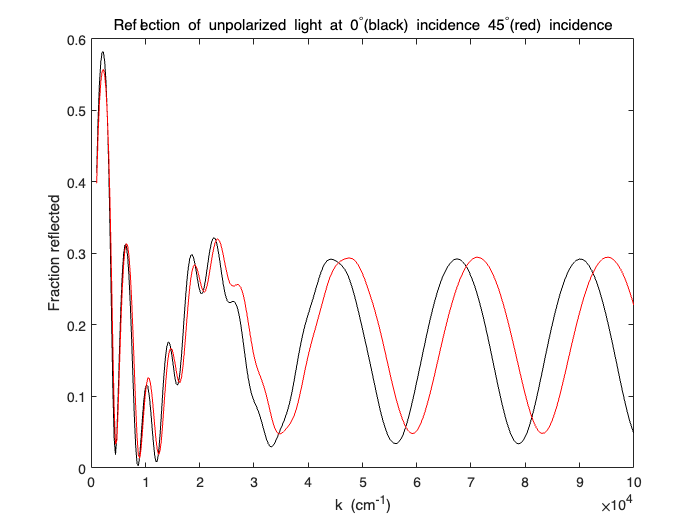

clc;
clear;
degree = pi/180;
%% sample 1
d_list = [inf,100,300,inf];
n_list = [1,2.2,3.3+0.3j,1];
ks=linspace(0.0001,0.01,400);
Rnorm=zeros(length(ks),2);
R45=zeros(length(ks),2);
for i=1:length(ks)
    k=ks(i);
    Rnorm(i,:)=coh_tmm('s',n_list, d_list, 0, 1/k);
    R45(i,:)=unpolarized_RT(n_list, d_list, 45*degree, 1/k);
end
kcm = ks * 1e7;%ks in cm^-1 
figure(1)
plot(kcm,Rnorm(:,1),'Color','black');
hold on 
plot(kcm,R45(:,1),'Color','red');
xlabel('k (cm^{-1})');
ylabel('Fraction reflected');
title('Reflection of unpolarized light at 0^{\circ}(black) incidence 45^{\circ}(red) incidence');

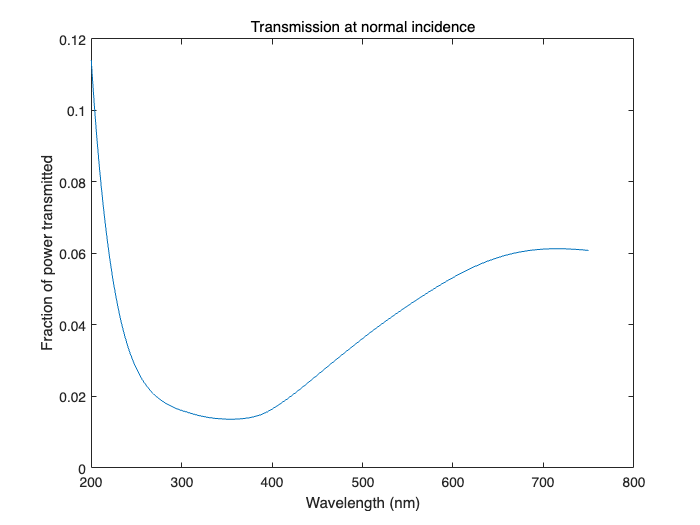

%% sample 2
material_nk_data = [200, 2.1+0.1j;300, 2.4+0.3j;400, 2.3+0.4j;500, 2.2+0.4j;750, 2.2+0.5j];
d_list = [inf,300,inf]; %in nm
lambda_list = linspace(200,750,400);%in nm
material_nk_fn = interp1(real(material_nk_data(:,1)),real(material_nk_data(:,2)),lambda_list,'pchip' )+1j*interp1(real(material_nk_data(:,1)),imag(material_nk_data(:,2)),lambda_list,'pchip' );
T_list = zeros(length(lambda_list));
for i=1:length(lambda_list)
    lambda_vac=lambda_list(i);
    n_list = [1, material_nk_fn(i), 1];
    [R,T]=coh_tmm('s',n_list,d_list,0,lambda_vac);
    T_list(i,:)=T;
end
figure(2)
plot(lambda_list,T_list)
xlabel('Wavelength (nm)')
ylabel('Fraction of power transmitted')
title('Transmission at normal incidence');